# Numerical Integration Techniques

## Gaussian Quadrature

The first technique we will discuss is Gaussian Quadrature. This method approximates integrals over a given interval using orthogonal functions, typically over the interval [-1, 1] using the following formulation


$$$\int_{-1} ^1 f(x) \; dx \approx \sum_{i = 1} ^n w_i f(x_i)$$$


where the weights $w_i$ are given by


$$w_i = \frac{2}{(1 - x_i^2)P_n'(x_i)^2}$$


where $P_n(x)$ is the nth Legendre polynomial, a special type of polynomial which is orthogonal over the interval [-1, 1] by the $L^2$ norm, and $x_i$ represents the ith root of this nth Legendre polynomial. While there is a built-in function to calculate the Legendre polynomials (legendreP(n, x)), we can also calculate them recursively using the following relation:


$$P_n(x) = \frac1n[(2n-1)xP_{n - 1}(x) + (n-1)P_{n-2}(x)]$$


For reference, here is a plot of the first few Legendre polynomials over the interval [-1, 1]

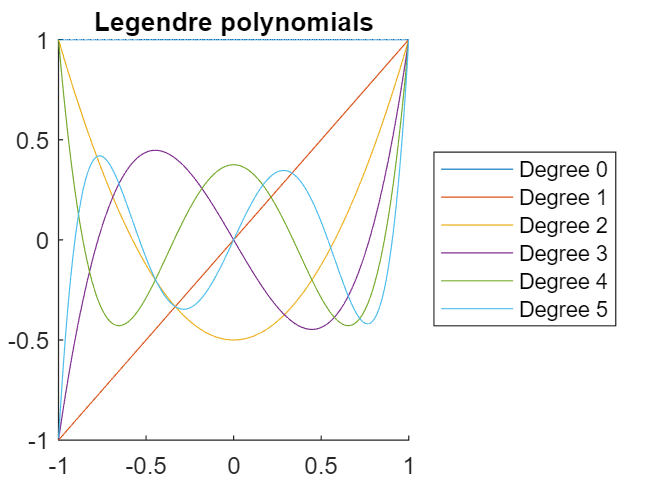

x = -1:0.01:1;
labels = num2cell("Degree " + string(0:5));
figure
hold on
for n = 0:5
    plot(x, legendreP(n, x))
end
title("Legendre polynomials")
legend(labels{:}, 'Location', 'eastoutside');
hold off

For the calculation of the Legendre polynomials, see the gaussQuad.m script. 

We can transform any integral over a real interval [a, b] into an integral from [-1, 1] using the following transformation:


$$\int_{a} ^b f(x) \; dx = \int_{-1} ^1 \frac{b - a}{2} f(\frac{b - a}{2} \xi + \frac{a+b}{2}) \; d\xi$$


For the implementation of this method, see gaussQuad.m. Here are some example evaluations.

% Integrating sin(x) from x = 0 to x = pi
y1 = @(x) sin(x);
disp("The integral of sin(x) from x = 0 to x = pi is")

The integral of sin(x) from x = 0 to x = pi is


gaussQuad(y1, 0, pi, 5)

ans = 2.0000


% Computing 0.5! = sqrt(pi)/2 using the Gamma function
y2 = @(x) x.^0.5.*exp(-x);
disp("0.5! is approximated to be")

0.5! is approximated to be


gaussQuad(y2, 0, 20, 15)

ans = 0.8889

disp("which is approximately sqrt(pi)/2 = 0.8862")

which is approximately sqrt(pi)/2 = 0.8862



% Compute double integral of e^(-(x^2+y^2)) from x,y = (0,0)
% to x,y = (10,10)
y3 = @(x, y) exp(-x.^2-y.^2);
disp("The double integral of e^(-(x^2+y^2)) from x,y = (0,0) " + ...
    "to x,y = (10,10) is")

The double integral of e^(-(x^2+y^2)) from x,y = (0,0) to x,y = (10,10) is


gaussQuad(y3, [0, 0], [10, 10], 12)

ans = 0.7855

## Monte Carlo Integration

By uniformly sampling points across the integration domain and calculating the average value of the function and then multiplying this value by the volume of the domain. Essentially, given the following integral:


$$I = \int_\Omega f(\bar x) \; dx$$


We have that


$$I \approx V \langle f \rangle$$


where $V$ is the volume of the subset $\Omega$ and $\langle f \rangle$ denotes the expected value of the function. To calculate the volume,  we simply generate several random points in a known region which encapsulates this domain. We then calculate the fraction of points contained within this region and multiply this ratio by the volume of this greater region. See monteCarloIntegral.m for the implementation of this method. A visualization of the Monte Carlo integration method is shown using the example of finding the area of a circle with a double integral.

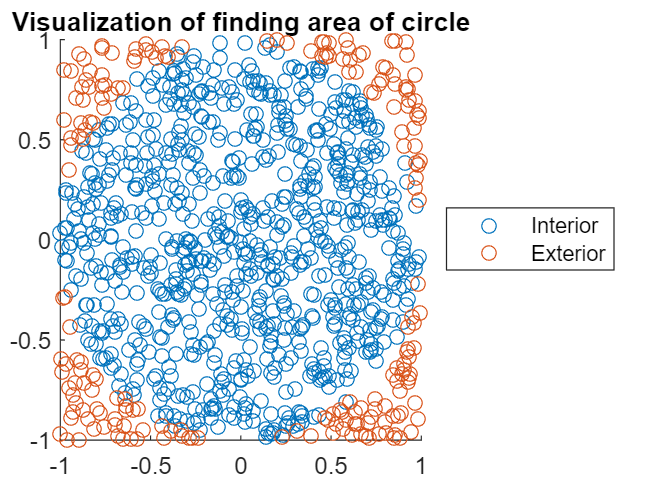

subset = @(x, y) x.^2 + y.^2 <= 1;
points = 2 .* rand(1000, 2) - 1;
point_args = mat2cell(points', ones(2, 1));
mask = subset(point_args{:});
interior = points(mask, :);
exterior = points(mask == 0, :);
figure
hold on
scatter(interior(:, 1), interior(:, 2))
scatter(exterior(:, 1), exterior(:, 2))
title("Visualization of area of circle")
legend("Interior", "Exterior", 'Location', 'eastoutside');

Here are some sample evaluations.

% Computing pi from area of a circle
boundary1 = subset;
f1 = @(x, y) 1;
disp("The area of the unit circle is approximately")

The area of the unit circle is approximately


monteCarloIntegral(f1, [-1,-1], [1,1], boundary1, 10000)

ans = 3.1492


% Evaluating the integral of f(x, y, z) = (xyz)^2 over a spherical region
boundary1 = @(x, y, z) x.^2 + y.^2 + z.^2 <= 1;
f1 = @(x, y, z) x.^2.*y.^2.*z.^2;
disp("The integral of (xyz)^2 over the unit sphere is")

The integral of (xyz)^2 over the unit sphere is


monteCarloIntegral(f1, [-1,-1,-1], [1,1,1], boundary1, 10000)

ans = 0.0132